# Controllers Design


$$M=k\sqrt{L_1 L_2 }=\;k\;\sqrt{L\cdot \frac{L}{2\ldotp 33}}=k\;\frac{L}{\sqrt{2\ldotp 33}}\;\;\;\;$$


### Dataset Upload

clc; clear all; close all

L_nom = 36.5e-6;
Lm_nom = 0.99*L_nom/sqrt(2.33);
C_nom = 100e-06;


load("dataset\20_30.mat"); C1 = C; k1 = k; Lm1 = k1*L_nom/sqrt(2.33);
load("dataset\25_35.mat"); C2 = C; k2 = k; Lm2 = k2*L_nom/sqrt(2.33);
load("dataset\30_35_40.mat"); C3 = C; k3 = k; Lm3 = k3*L_nom/sqrt(2.33);
load("dataset\45_50_60.mat"); C4 = C; k4 = k; Lm4 = k4*L_nom/sqrt(2.33);

Lm_bm = mean([Lm1, Lm2, Lm3, Lm4]);
C_bm = mean([C1, C2, C3, C4]);

fprintf('Variation to Real Value\n Lm: %0.3f %%\t C: %0.3f %%', (1-Lm_bm/Lm_nom)*100, (1-C_bm/C_nom)*100);

Variation to Real Value
 Lm: 33.533 %	 C: -19.428 %

### System Definition

DuCy=30;  % The range is 0-60 % duty cycle
I_Lo=0; V_Co=0;
Vg=5; Vd=0.7;
Vs=[Vg Vd];
X=[I_Lo V_Co];


[A,B,C,D,G_nom] =flyback_ss(Vs,X,DuCy,Lm_bm,C_bm);
G_nom

G_nom =
 
           3.511e10
  ---------------------------
  s^2 + 1.907e04 s + 8.244e10
 
Continuous-time transfer function.



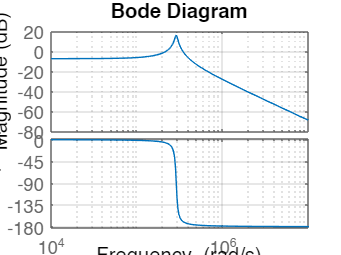

bode(G_nom); grid on

Gz = c2d(G_nom,1e-5,'Tustin')

Gz =
 
  0.2781 z^2 + 0.5561 z + 0.2781
  ------------------------------
     z^2 + 0.6723 z + 0.9396
 
Sample time: 1e-05 seconds
Discrete-time transfer function.



### Internal Model Control

s=tf('s');
stepinfo(G_nom)

ans = struct with fields:
         RiseTime: 3.7234e-06
    TransientTime: 4.0611e-04
     SettlingTime: 4.0611e-04
      SettlingMin: 0.0802
      SettlingMax: 0.8095
        Overshoot: 90.0893
       Undershoot: 0
             Peak: 0.8095
         PeakTime: 1.0942e-05


lambda = 4.06e-4;
n = 2;

F = 1/(lambda*s+1)^n;
Gc = (1/G_nom)*F

Gc =
 
    s^2 + 1.907e04 s + 8.244e10
  --------------------------------
  5787 s^2 + 2.851e07 s + 3.511e10
 
Continuous-time transfer function.



P_tilde = G_nom

P_tilde =
 
           3.511e10
  ---------------------------
  s^2 + 1.907e04 s + 8.244e10
 
Continuous-time transfer function.



F_d = c2d(F,80e-9,'Tustin')

F_d =
 
                                     
  9.705e-09 z^2 + 1.941e-08 z        
                                     
                          + 9.705e-09
                                     
  -----------------------------------
                            
          z^2 - 2 z + 0.9996
                            
 
Sample time: 8e-08 seconds
Discrete-time transfer function.



Gc_d = c2d(Gc,80e-9,'Tustin')

Gc_d =
 
                                     
  0.0001729 z^2 - 0.0003455 z        
                                     
                          + 0.0001727
                                     
  -----------------------------------
                            
          z^2 - 2 z + 0.9996
                            
 
Sample time: 8e-08 seconds
Discrete-time transfer function.



P_tilde_d = c2d(P_tilde,80e-9,'Tustin')

P_tilde_d =
 
                                     
  5.612e-05 z^2 + 0.0001122 z        
                                     
                          + 5.612e-05
                                     
  -----------------------------------
                              
        z^2 - 1.998 z + 0.9985
                              
 
Sample time: 8e-08 seconds
Discrete-time transfer function.



### Lag-Lead Compensator

% Step 1: Uncompensated system Bode plot
s = tf('s');
%G = 1 / (s * (s + 3));  % Example transfer function, replace with your own
[Gm,Pm, ~, crossover_freq] = margin(G_nom);  % Get current gain crossover frequency

Unrecognized function or variable 'G'.


% Step 2: Choose new gain crossover frequency
new_crossover_freq = crossover_freq / 10;  % Choose new crossover frequency one decade below

% Step 3: Determine beta and other corner frequency
desired_phase_margin = 60;  % Desired phase margin in degrees
desired_gain_margin = 4;  % Desired gain margin in dB
attenuation = -20 * log10(sqrt((1 + sin(desired_phase_margin*pi/180))^2 / (1 - sin(desired_phase_margin*pi/180))^2))

beta = 10^(-attenuation / 20);  % Compute beta from attenuation
T = 1 / (beta * new_crossover_freq);  % Compute T from beta and new crossover frequency

% Step 4: Calculate Kc
K = abs(dcgain(G));  % Get the DC gain of the uncompensated system
Kc = K / beta;  % Calculate the compensator gain

% Create the lag compensator transfer function
Gc = Kc * ((s + 1 / (T * beta)) / (s + 1 / T));

margin(G)
hold on
% Step 1 (revisited): Compensated system Bode plot
margin(G * Gc);  % Plot Bode diagram and compute gain/phase margin
hold off


### Lag-Lead compensator

% Desired phase and gain margins
desired_phase_margin = 60; % in degrees
desired_gain_margin = 6; % in dB

% Plant transfer function
s = tf('s');

% Calculate the poles and damping factors
[~, ~, poles] = damp(G_nom);
% Find the index of the dominant pole
[~, index] = min(abs(real(poles)));
% Select the dominant pole
dominant_pole = -poles(index)

dominant_pole = 6.3554e+03 - 1.8800e+05i

w = abs(dominant_pole)

w = 1.8811e+05

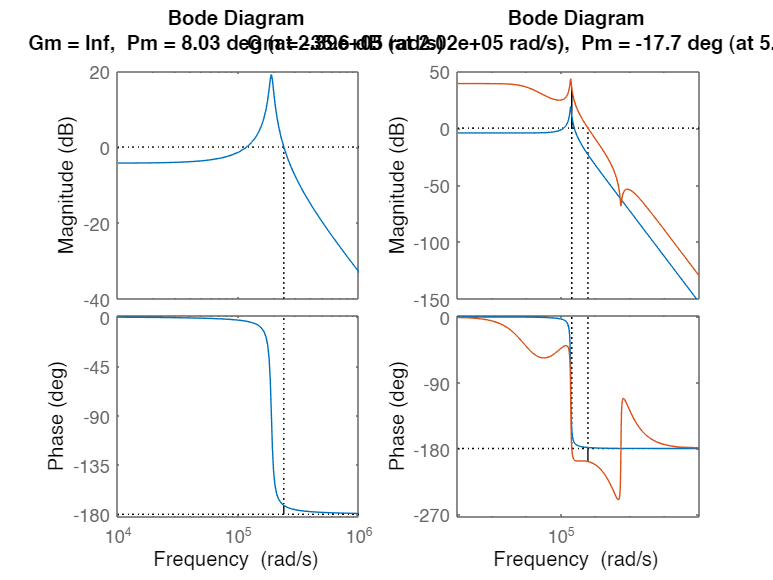

T = 1/(w/20);
tau = 1/(w/2);

C_lag = (tau*s + 1)/(T*s + 1);

wc = 600000;
K = 1/abs(freqresp(C_lag*G_nom,wc));
C_lag = K*C_lag;

wn=5370000;
xci_z=0.03; %aggiustate xci_z e xci_p per rendere il filtro più o meno selettivo
xci_p=0.9;
notch=(s^2+2*xci_z*wn*s+wn^2)/(s^2+2*xci_p*wn*s+wn^2);

figure
subplot(1,2,1)
margin(G_nom)
subplot(1,2,2)
bode(G_nom)
hold on
margin(G_nom*C_lag*notch)
hold off

getPeakGain(feedback(1,G_nom*C_lag*notch))

ans = 3.2646

### PI Controller with Notch Filter

Vorrei un $\omega_c$ prossima all'antirisonanza (che è attorno a 100 rad/s)

wc=190970; % Desired Omega

L'azione integrale mi sfasa, la metto almeno una decade prima.

wi=wc/0.1; % pulsazione azione integrale
Ti=1/wi;

Il mio controllore sarà


$$C(s)=K_p \left(1+1/(Ti\cdot s)\right)=K_p C_o(s)$$


con $C_o(s)=$

s=tf('s');
Co=1+1/(Ti*s);

Calcolo $K_p$ in modo che $C(s)*P(s)=K_p \left(C_o(s)*P(s)\right)$ abbia modulo 1 in $\omega_c$. 

$|K_p \left(C_o(j\omega_c)*P(j\omega_c)\right)|=1 $ quindi $K_p=1/| \left(C_o(j\omega_c)*P(j\omega_c)\right)|$

Kp=1/abs(freqresp(Co*G,wc));
C_old=Kp*Co

#### Notch filter

damp(G)
wn=5370000;
xci_z=0.03; %aggiustate xci_z e xci_p per rendere il filtro più o meno selettivo
xci_p=0.9;
notch=(s^2+2*xci_z*wn*s+wn^2)/(s^2+2*xci_p*wn*s+wn^2);
figure
subplot(1,2,1)
bode(notch)
grid on
Kp=1/abs(freqresp(Co*G*notch,wc));
c=Kp*Co*notch;

subplot(1,2,2)
bode(C_old*G); hold on
margin(c*G); hold off
grid on
legend('Loop','Loop with Notch filter')
getPeakGain(feedback(1,c*G))
